# Filter of input signal

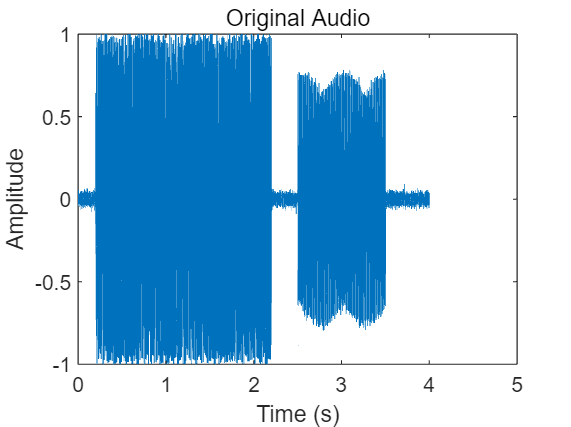

[audio_data, Fs] = audioread("chord1.wav");
% Calculate the length of input audio data in seconds
len_time = length(audio_data) / Fs;
% Create time series to plot the data
time = linspace(0, len_time, length(audio_data));

%% Plot of original signal %%
% Figure1: Amplitude VS Time
figure(1);
plot(time, audio_data);
title('Original Audio');
xlabel('Time (s)');
ylabel('Amplitude');

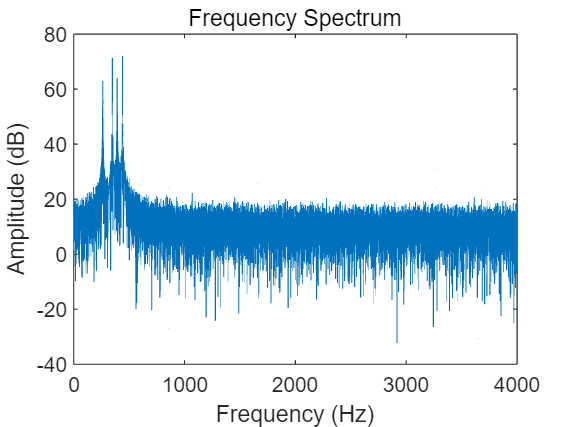


% Frequency analysis
nfft = 2^nextpow2(length(audio_data)); % Selecting the number of FFT points
fft_result = fft(audio_data, nfft);
fft_result = fft_result(1:nfft/2); 
% Calculate the frequency axis
frequencies = (0:nfft/2-1) * Fs / nfft;

% Figure2: Amplitude(DB) VS Frequency
figure(2);
plot(frequencies, 20*log10(abs(fft_result))); 
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');

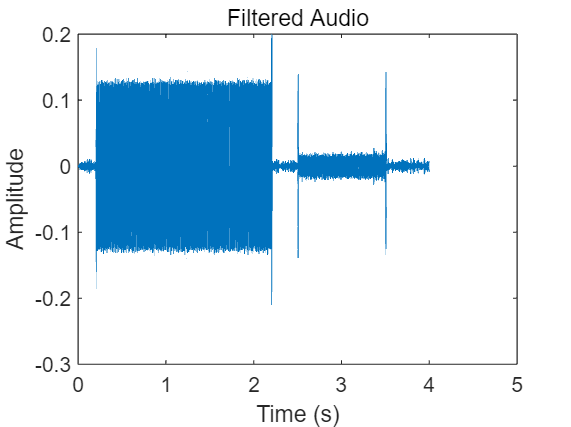


%% Filter design %%
% Define parameters for the bandpass filter
center_freq =550;
lower_freq = 500;
upper_freq = 600;
filter_order = 100;

% Normalize frequencies
normalized_center_freq = center_freq / (Fs/2);
normalized_lower_freq = lower_freq / (Fs/2);
normalized_upper_freq = upper_freq / (Fs/2);

% Design a bandpass filter
bandpass_filter = fir1(filter_order, [normalized_lower_freq normalized_upper_freq], 'bandpass');

% Apply the bandpass filter to the audio data
filtered_audio = filter(bandpass_filter, 1, audio_data);

%% Filter apply %%
filtered_fft_result = fft(filtered_audio, nfft);
filtered_fft_result = filtered_fft_result(1:nfft/2);

%% Plot of filtered signal %%
% Figure3: Filtered - Amplitude VS Time
figure(3);
plot(time, filtered_audio);
title('Filtered Audio');
xlabel('Time (s)');
ylabel('Amplitude');

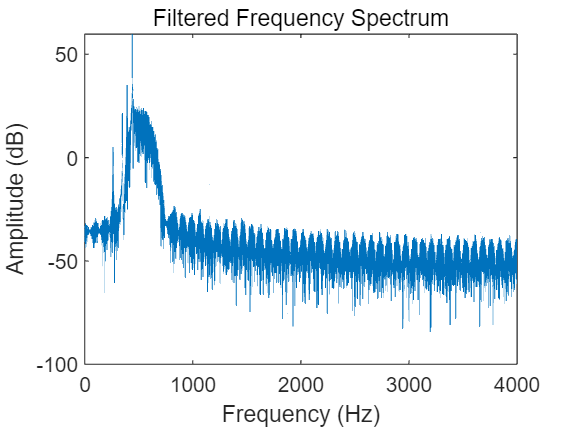


% Figure4: Filtered - Amplitude(DB) VS Frequency
figure(4);
plot(frequencies, 20*log10(abs(filtered_fft_result)));
title('Filtered Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');

## Process of filtered signal

% sound(audio_data,Fs)
% sound(filtered_audio,Fs)
% Calculate the energy of filtered audio signal
Energy = eng(1,length(filtered_audio),filtered_audio)

Energy = 126.6486

% Judge whether target frequency is detected to continue executing following steps
if Energy>40
    x = 1;
end

## Function set

function [energ] = eng(timeLeft,timeRight,amp)
    energ=0;
    for i = timeLeft:timeRight
        energ = energ + amp(i)^2;
    end
end
